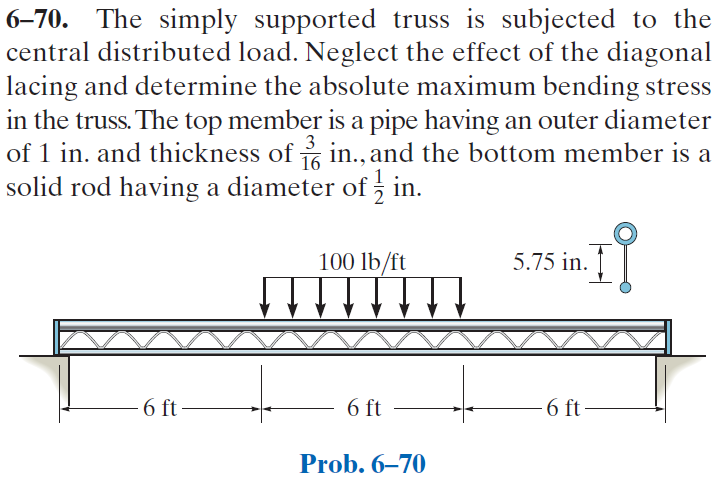

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-70P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-70P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'R1', 0);
b = b.add('reaction', 'force', 'R2', 18*u.ft);
b = b.add('distributed', 'force', -100*u.lbf/u.ft, [6 12]*u.ft);
b.L = 18*u.ft;

# section properties

Do = u.in;
Di = 2*(Do/2-3/16*u.in);
D = 1/2*u.in;
yc = [D/2 D+5.75*u.in+Do/2];
Ac = [sympi/4*D^2 sympi/4*(Do^2-Di^2)];
Ic = [sympi/4*(D/2)^4 sympi/4*((Do/2)^4-(Di/2)^4)];
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic);
b.I = rewrite(sum(In), u.ft);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{14948499456000\,x\,\left(234\,{\mathrm{ft}}^{2}-x^{2}\right)}{27201721\,\text{E}\,\pi }\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{4}} & \text{ if }x\leq 6\,\mathrm{ft}\\ -\frac{1245708288000\,\left(x^{4}-36\,x^{3}\,\mathrm{ft}+216\,x^{2}\,{\mathrm{ft}}^{2}+1944\,x\,{\mathrm{ft}}^{3}+1296\,{\mathrm{ft}}^{4}\right)}{27201721\,\text{E}\,\pi }\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{5}} & \text{ if }x\in \left(6\,\mathrm{ft},12\,\mathrm{ft}\right]\\ -\frac{14948499456000\,\left(x-18\,\mathrm{ft}\right)\,\left(x^{2}-36\,x\,\mathrm{ft}+90\,{\mathrm{ft}}^{2}\right)}{27201721\,\text{E}\,\pi }\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{4}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{44845498368000\,\left(78\,{\mathrm{ft}}^{2}-x^{2}\right)}{27201721\,\text{E}\,\pi }\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{4}} & \text{ if }x\leq 6\,\mathrm{ft}\\ \frac{4982833152000\,\left(x-9\,\mathrm{ft}\right)\,\left(-x^{2}+18\,x\,\mathrm{ft}+54\,{\mathrm{ft}}^{2}\right)}{27201721\,\text{E}\,\pi }\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{5}} & \text{ if }x\in \left(6\,\mathrm{ft},12\,\mathrm{ft}\right]\\ -\frac{44845498368000\,\left(x^{2}-36\,x\,\mathrm{ft}+246\,{\mathrm{ft}}^{2}\right)}{27201721\,\text{E}\,\pi }\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{4}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} 300\,x\,\mathrm{lbf} & \text{ if }x<6\,\mathrm{ft}\\ -50\,\left(x^{2}-18\,x\,\mathrm{ft}+36\,{\mathrm{ft}}^{2}\right)\,\frac{\mathrm{lbf}}{\mathrm{ft}} & \text{ if }x\in \left[6\,\mathrm{ft},12\,\mathrm{ft}\right]\\ -300\,\left(x-18\,\mathrm{ft}\right)\,\mathrm{lbf} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} 300\,\mathrm{lbf} & \text{ if }x<6\,\mathrm{ft}\\ -100\,\left(x-9\,\mathrm{ft}\right)\,\frac{\mathrm{lbf}}{\mathrm{ft}} & \text{ if }x\in \left[6\,\mathrm{ft},12\,\mathrm{ft}\right]\\ -300\,\mathrm{lbf} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<6\,\mathrm{ft}\\ -100\,\frac{\mathrm{lbf}}{\mathrm{ft}} & \text{ if }x\in \left[6\,\mathrm{ft},12\,\mathrm{ft}\right]\\ 0 & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} R_{1} & 300\,\mathrm{lbf}\\ R_{2} & 300\,\mathrm{lbf} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

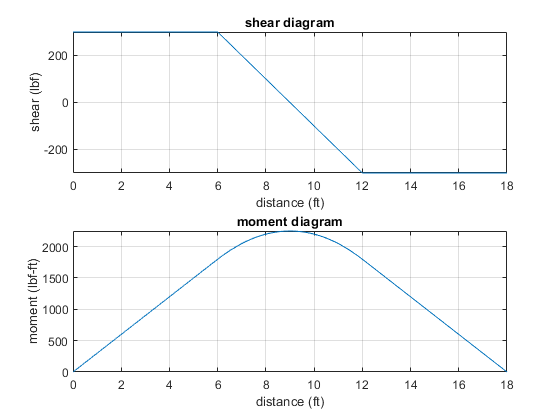

beam.shear_moment(m, v, [0 b.L], {'lbf' 'ft'});

# absolute maximum bending stress

M_max = m(b.L/2)

$$M\_max = 2250\,\mathrm{ft}\,\mathrm{lbf}$$

C = symmax([yn D+5.75*u.in+Do-yn]);
b.I = rewrite(b.I, u.in);
sigma_max = rewrite(M_max*C/b.I, u.ksi);
sigma_max_vpa = vpa(sigma_max, 4) %#ok<NASGU> 

$$sigma\_max\_vpa = 22.13\,\mathrm{ksi}$$

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear sigma_max_vpa;